tradingBacktest

Stock buy and sell is condicted in the market opening time. Transaction costs & slipage costs are calculated and included. 

% Capital allocation in the beginning of the day 
% Capital allocation is equally weighted
% paramsInput = [70	106	5	3	8	14	107	29	4	4	6]
m = matfile("pricevolumedata.mat","Writable",true) ;
tradingSignalTT = m.tradingSignalTT ;
tradingSignal = tradingSignalTT.Variables ;

capitalAllocThresh = 5;
NdailySignal = sum (tradingSignal, 2) ;
dailyCapApploc = ones (size(NdailySignal,1),1) ./ NdailySignal  ;
dailyCapApploc (NdailySignal<capitalAllocThresh) = 1/capitalAllocThresh ;
dailyCapApploc (NdailySignal==0) = 0 ;
dailyCapApploc(isinf(dailyCapApploc)) = 0 ;
capAllocbod = tradingSignal .* dailyCapApploc ;


% Rebalancing capital allocation in the following day
capAllocbodyest = capAllocbod;
capAllocbodyest (1,:) = 0 ;
capAllocbodyest (2:end,:) = capAllocbod (1:end-1,:) ;
rebalCapAlloc = capAllocbod - capAllocbodyest ;


% Transaction buy sell fee
buyFee = 0.15/100;
sellFee = 0.25/100;

buyMarker = rebalCapAlloc>0 ;
sellMarker = rebalCapAlloc<0 ;
buySellMarker = buyMarker + sellMarker ; % use later in slipage cost calculation
buyFeeMap = buyMarker .* buyFee ;
sellFeeMap = sellMarker .* sellFee ;
tradingFeeMap = buyFeeMap + sellFeeMap ;

tradingFeeRaw = tradingFeeMap .* rebalCapAlloc ;
tradingFee = -abs(tradingFeeRaw) ;


% Slipage cost
% When the market open, buy price will target the best offer and sell price
% will target best bid which are assumed to be the open price
m = matfile("pricevolumedata.mat","Writable",true) ;
openpriceTT = m.openpriceTT ;
closepriceTT = m.closepriceTT ;

closeprice = closepriceTT.Variables ;
closepriceSlipage = closeprice;
closepriceSlipage(1,:) = 0 ;
closepriceSlipage(2:end,:) = closeprice(1:end-1,:) ;
slipageCostRaw = openpriceTT.Variables ./ closepriceSlipage -1 ;
slipageCostRaw (1,:) = 0 ;
slipageCost = (slipageCostRaw .* capAllocbod) .* buySellMarker ;


% Raw daily return
priceRetClose = closeprice;
priceRetClose (2:end,:) = closeprice(2:end,:) ./ closeprice (1:end-1,:) -1 ;
priceRetClose (1,:) = 0 ;
filteredRawDailyRet = (priceRetClose .* tradingSignal) .* capAllocbod ;


% Net daily return
netDailyRet = (filteredRawDailyRet + tradingFee + slipageCost) ;


% Portfolio daily return
portDailyRet = sum(netDailyRet,2) ;

sz = [size(portDailyRet,1),1];
varType = ["double"] ;
rowTimes = closepriceTT.Time;
varName = "portDailyRet" ;
portDailyRetTT = timetable('Size', sz, 'VariableTypes', varType, 'RowTimes', rowTimes, 'VariableNames',varName) ;
portDailyRetTT.Variables = portDailyRet ;

% Portfolio cumulative daily return
portCumRetTT = ret2tick (portDailyRetTT) ;


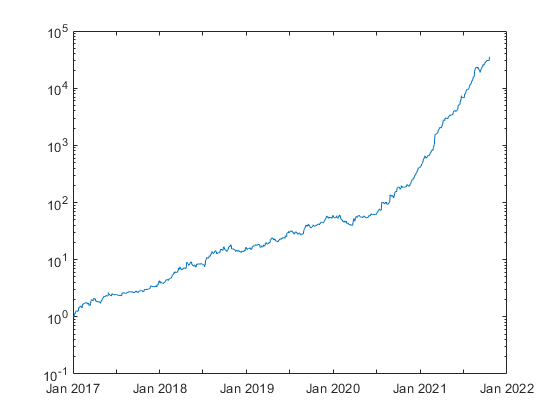

% plot 

semilogy(portCumRetTT.Time, portCumRetTT.Variables)

% Statistics

% Portfolio Value
portCumRet = portCumRetTT.Variables ;
portEndValue = portCumRet(end,:)

portEndValue = 3.5105e+04

portMinValue = min(portCumRetTT.Variables)

portMinValue = 0.9823

portMaxValue = max(portCumRetTT.Variables)

portMaxValue = 3.5105e+04


% CAGR
nYear = yearfrac (rowTimes(1,:), rowTimes(end,:)) 

nYear = 4.8027

CAGR = (portEndValue ^ (1/nYear)) - 1 

CAGR = 7.8392


% Average return

dailyRetAvg = mean(portDailyRet)

dailyRetAvg = 0.0092

dailyRetMin = min(portDailyRet)

dailyRetMin = -0.1270

dailyRetMax = max(portDailyRet)

dailyRetMax = 0.2647


% drawodown
[MaxDD,MaxDDIndex] = maxdrawdown(portCumRetTT.Variables) ;
MaxDD

MaxDD = 0.3150

drawdownDate = rowTimes (MaxDDIndex)

drawdownDate = 2×1 datetime array
   2019-12-04
   2020-03-17



% Risk-reward ratios
risklessAssetRet = 0 ;
sharpeRatio = sharpe(portDailyRetTT.Variables, risklessAssetRet) *sqrt (252)

sharpeRatio = 4.2703

% Remove temporary variables
clear dailyCapApploc capAllocbodyest rebalCapAlloc capAllocbod NdailySignal tradingSignal
clear buyMarker sellMarker buySellMarker buyFeeMap sellFeeMap tradingFeeMap tradingFeeRaw tradingFee
clear closepriceSlipage slipageCostRaw slipageCost 
clear priceRetClose filteredRawDailyRet netDailyRet
clear openpriceTT closepriceTT closeprice 